# Estructuras de datos: Matrices

La estructura de datos más básica de MATLAB es la matriz. Una matriz es un arreglo rectangular bidimensional de elementos de datos dispuestos en filas y columnas. Los elementos pueden ser números, valores lógicos (verdadero o falso), fechas y horas, cadenas o algún otro tipo de datos de MATLAB.

De forma general se puede pensar que casi todo dentro de MATLAB es una matriz, incluso un solo número se almacena como una matriz.

% Ingrese su código aquí :)

#### Observación

Un arreglo (**array** en inglés) y una matriz no son lo mismo. Un arreglo es una colección o grupo de objetos (datos, variables, etc.), mientras que **una matriz es un tipo de arreglo**, más específicamente es un arreglo homogéneo porque únicamente puede contener elementos del mismo tipo, además que una matriz es bidimensional: sólo tiene filas y columnas. Un arreglo no necesariamente es bidimensional, es decir, no necesariamente tiene filas y columnas, también puede tener más dimensiones.

**Fig. 1.** Tipos de arreglos.

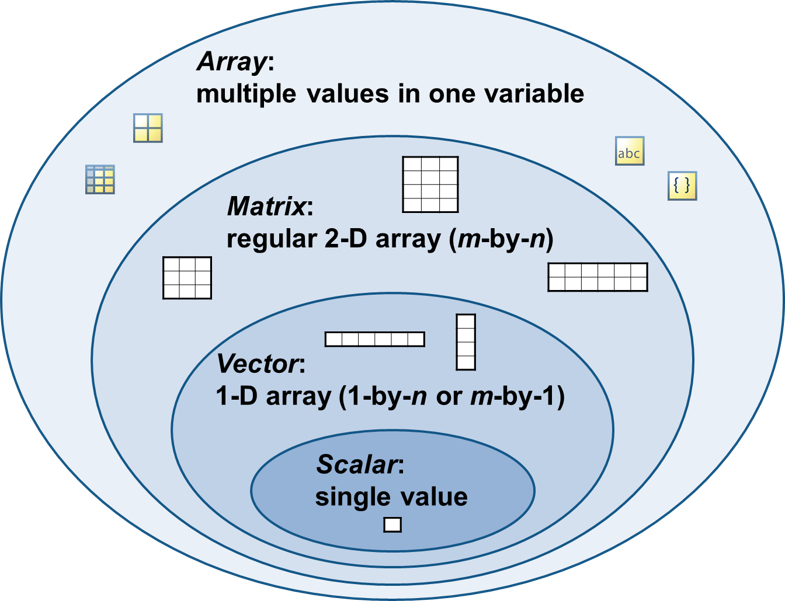

*Tomado de MATLAB Fundamentals (R2022a) de MathWorks.*

## Diferencia entre escalar, vector y matriz

Existen 3 conceptos dentro de MATLAB que se debe saber diferenciar bien cuando se trabajan con matrices:

- **Escalar**: matriz de dimensiones $1\times 1$.

- **Vector**: matriz de dimensiones $1\times m$ o $n\times 1$.

- **Matriz**: agrupación de filas y columnas. Es de dimensiones $m\times n$.

### Escalar

Como se mencionó, un escalar posee las dimensiones $1\times 1$.

% Ingrese su código aquí :)

### Vector

Un vector puede ser de dos tipos: **vector fila** ($1\times m$) o **vector columna** ($n\times 1$). La característica que destaca de cada tipo de vector es que posee o bien una sola fila o bien una sola columna.

Ahora que vamos a definir nuestra primera matriz, es importante conocer lo siguiente:

- **Una matriz se define con corchetes** `[]`

- Para separar las columnas se utiliza la coma `,`

- Para separar las filas se utiliza el punto y coma `;`

% Ingrese su código aquí :)

### Matriz

Para crear una matriz utilizamos tanto `;` como `,` para separar las filas y columnas, respectivamente. Por ejemplo, se tiene la siguiente matriz:


$$A=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
4 & 5 & 6\\
7 & 8 & 9
\end{array}\right\rbrack$$


Ahora creémosla dentro de MATLAB. Esto se realiza a partir de las filas.

% Ingrese su código aquí :)

Notemos que primero se crea la fila $\left\lbrack 1\;2\;3\right\rbrack$, luego se crea la fila $\left\lbrack 4\;5\;6\right\rbrack$ y finalmente se crea la fila $\left\lbrack 7\;8\;9\right\rbrack$. Y estas filas están separadas por el punto y coma `;`.

#### Observación

Siempre se debe recordar que una matriz es un arreglo ordenado de filas y columnas, por ende, si se crea una matriz con una fila de 4 elementos y otra fila de 3 elementos, entonces obtendremos un error.


$$A=\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
5 & 6 & 7 & ?
\end{array}\right\rbrack$$


En la forma incorrecta nos falta un elemento para que la matriz esté completa, por eso ocurre el error. En ese espacio $?$ debería ir algún valor para que la matriz se cree sin problemas.

### Matriz vacía

Antes de continuar es menester conocer la matriz vacía. Esta matriz se caracteriza por no tener elementos, lo cual le da su nombre.

Para crear una matriz vacía se utiliza la función `empty`, pero de una manera ligeramente diferente a como hemos trabajado hasta este momento.

Es decir, se debe utilizar la notación punto indicando el nombre del tipo de dato (o clase) y luego que se trata de una matriz vacía.

% Ingrese su código aquí :)

#### Observación

Esta matriz se puede presentar de diferentes formas, no únicamente por dos corchetes sin elementos. Esto dependerá del tipo de dato con el que se esté trabajando, pero es más que suficiente con leer qué tipo de matriz se obtiene. Cuando es una matriz vacía MATLAB suele indicar que se trata de una, además del tipo de matriz.

## Crear matrices adecuadamente

La anterior forma de crear matrices es correcta, pero no es fácil de leer (a menos que se tenga un poco de experiencia). Es por esto que MATLAB permite definir matrices considerando lo siguiente:

- Para separar columnas, en lugar de utilizar la coma `,` se utiliza un espacio en blanco (o varios).

- Para separar filas, en lugar de utilizar el punto y coma `;` se utilizar un intro (o "enter", salto de línea, etc.).

Con esto se puede crear matrices de manera muy sencilla, rápida y agradable a la vista.

% Ingrese su código aquí :)

### Operador `'`

Si bien todavía no hemos entrado a las operaciones con matrices, podríamos empezar con el operador ' (o apóstrofe, comilla simple, etc.). Este operador permite transponer una matriz, es decir, convertir las filas en columnas y las columnas en filas.

Esto es particularmente útil cuando vamos a definir vectores columna, puesto que podemos crear un vector fila y al transponerlo se vuelve vector columna, lo que facilita crear este tipo de vectores.

% Ingrese su código aquí :)

### Notación científica en matrices

Previamente estudiamos la notación científica dentro de MATLAB, pero ese estudio fue para escalares. Cuando se trata de matrices es ligeramente diferente. La diferencia radica en la visualización de la notación científica de una matriz.

% Ingrese su código aquí :)

Por defecto, la notación científica de una matriz siempre se visualizará cuando los elementos de ésta sean muy grandes o muy pequeños.

## Crear vectores con el operador dos puntos y la función `linspace`

Es posible crear vectores linealmente espaciados con el operador dos puntos (`:`) o con la función `linspace`. Sin embargo, se debe diferenciar cuánto utilizar un método u otro.

**Fig. 2.** Operador dos puntos VS. función `linspace`.

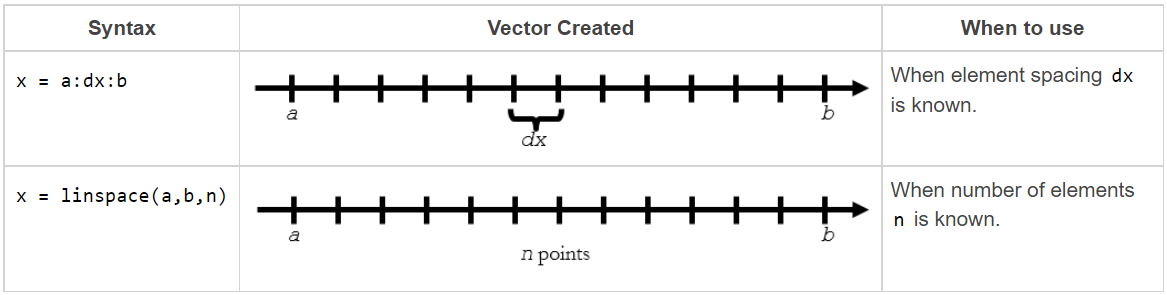

*Tomado de MATLAB Fundamentals (R2022a) de MathWorks.*

### Operador dos puntos `:`

El operador dos puntos `:` permite crear vectores linealmente espaciados conociendo:

- el número inicial

- el número final

- el espaciamiento

Lo que se desconoce a priori con el operador dos puntos `:` es el número de elementos.

% Ingrese su código aquí :)

#### Observación

Cuando el espaciamiento es $1$ no es necesario indicarlo porque MATLAB sobreentiende que cuando no se indica el espaciamiento, entonces su valor es $1$.

% Ingrese su código aquí :)

Si los números generados con el espaciamiento indicado no llega exactamente al número final, entonces tomará el número anterior al número final que sí cumpla con el espaciamiento.

% Ingrese su código aquí :)

Si el espaciamiento o numero final es inadecuado, es decir, no hay números entre el número inicial y número final con el espaciamiento indicado, entonces el resultado es la matriz tipo `double` vacía.

% Ingrese su código aquí :)

### Función `linspace`

La función `linspace` permite crear vectores linealmente espaciados conociendo:

- el número inicial

- el número final

- el número de elementos

Lo que se desconoce a priori con la función `linspace` es el espaciamiento.

% Ingrese su código aquí :)

#### Observaciones

Cuando el número de elementos es $100$ no es necesario indicarlo porque MATLAB sobreentiende que cuando no se indica el número de elementos, entonces su valor es $100$.

% Ingrese su código aquí :)

### Función `logspace`

La función `logspace` permite crear vectores logarítmicamente (en base 10) espaciados conociendo:

- la potencia del número inicial

- la potencia del número final

- el número de elementos

Es decir, si se quisieran cierta cantidad de números logarítmicamente espaciados en base 10 con el número inicial ${10}^0$ hasta el número final ${10}^4$, entonces la potencia del número inicial es $0$ y la potencia del número final es $4$.

Lo que se desconoce a priori con la función `logspace` es el espaciamiento.

% Ingrese su código aquí :)

#### Observaciones

Cuando el número de elementos es $50$ no es necesario indicarlo porque MATLAB sobreentiende que cuando no se indica el número de elementos, entonces su valor es $50$.

% Ingrese su código aquí :)

### Dimensión predominante en una matriz

La dimensión predominante, o principal, cuando se trabaja con matrices es la columna (o también se le llama dimensión `1`). Luego de la dimensión predominante se encuentra la fila (dimensión secundaria), o dimensión `2`.

Si se trabaja con vectores esto no es importante, pero con matrices $m\times n$ si debe considerarse siempre.

Por ejemplo, veamos qué ocurre con la función `sum` (suma).

% Ingrese su código aquí :)

#### Observación

Casi todas las funciones dentro de MATLAB trabajarán con las columnas como dimensión predominante y las filas como dimensión secundaria, pero existen ciertas excepciones que trabajarán con las filas como dimensión predominante y las columnas como dimensión secundaria.

Un ejemplo de estas excepciones es la función `circshift`.

Entonces aquí resalta todavía más la necesidad de consultar la documentación cuando notemos un comportamiento extraño en una función, inclusive antes de utilizar una función que no recordemos bien su funcionamiento. Quizá estemos intentando hacer algo, pero la función trabaje de otra forma.

#### Observación

Evidentemente se debe considerar esto dependiendo de lo que se requiera realizar, además de si la función utilizada permite o no el cálculo en otras dimensiones.

Por ejemplo, la función `sqrt` (raíz cuadrada) no permite calcular en ninguna dimensión. Esta función directamente aplica la raíz cuadrada a cada elemento de la matriz.

% Ingrese su código aquí :)

Aunque bueno, ¿cuál sería el objetivo de hacer una raíz cuadrada por columna o fila únicamente?

Nunca está demás leer un poco de la documentación de una función para conocer las capacidades y limitaciones de ésta.

## Determinar las dimensiones, número de elementos y orden de una matriz

Cuando tenemos una matriz, es impotante saber cuáles son sus dimensiones, cuántos elementos hay en esta matriz o cuál es su orden. A continuación se presentan las funciones para este fin.

### Funciones `size` y `length`

La función `size` permite conocer las dimensiones de una matriz.

% Ingrese su código aquí :)

El primer número representa el número de filas y el segundo número representa el número de columnas.

Por otra parte, la función `length` devuelve el valor de la dimensión más grande.

% Ingrese su código aquí :)

La función `length` es especialemente útil cuando se trabajan con vectores, puesto que la dimensión más grande coincide con el número de elementos del vector. No obstante, cuando se quiere conocer cuál es el valor de la dimensión más grande únicamente, también resulta bastante útil.

### Función `numel`

La función `numel` permite conocer el número de elementos dentro de una matriz.

% Ingrese su código aquí :)

### Función `ndims`

La función `ndims` permite conocer el número de dimensiones de un arreglo.

% Ingrese su código aquí :)

Esto resulta especialmente útil cuando ya no sólo se trabaja con matrices (las cuales tienen 2 dimensiones) si no que se trabajan con arreglos de 3, 4 o más dimensiones.

## Concatenar matrices

Teniendo en cuenta las dimensiones de las matrices, es posible concatenar (unir) una o más matrices siempre y cuando el resultado sea una matriz $m\times n$.

Para concatenar matrices también se utilizar corchetes `[]`.

**Fig. 3.** Concatenación vertical.

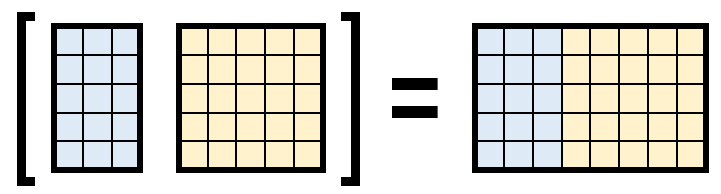

**Fig. 4.** Concatenación horizontal.

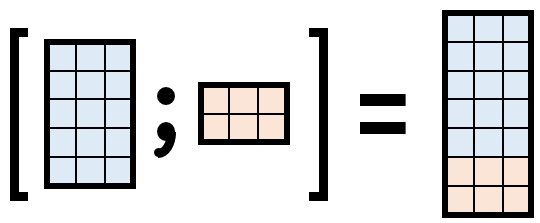

**Fig. 5.** Concatenación combinada.

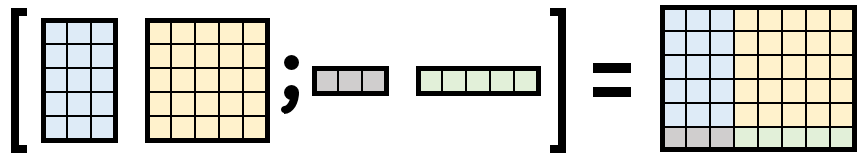

*Todas las figuras fueron tomadas de MATLAB Fundamentals (R2022a) de MathWorks.*

% Ingrese su código aquí :)

#### Observación

Así como se pueden concatenar matrices a través de vectores, también es posible hacerlo a través de otras matrices o incluso a través de vectores y matrices simultáneamente. Lo que siempre se debe tener en cuenta son las dimensiones de la matriz resultante.

% Ingrese su código aquí :)

## Redimensionar matrices

Muchas funciones en MATLAB pueden tomar los elementos de una matriz existente y colocarlos en una forma o secuencia diferente. Esto puede ser útil para preprocesar los datos para cálculos posteriores o analizar los datos.

**Fig. 6.** Redimensionamiento de una matriz.

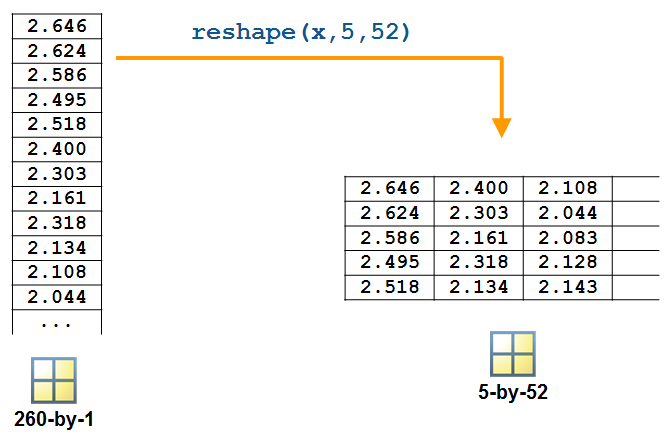

*Tomado de MATLAB Fundamentals (R2022a) de MathWorks.*

### Función `reshape`

La función `reshape` permite redimensionar una matriz.

Lo que se debe considerar es que la nueva matriz redimensionada debe contener a todos los elementos de la matriz original. Es decir, el producto de de las dimensiones de cualquier matriz redimensionada debe ser igual al producto de las dimensiones de la matriz original.

Por ejemplo, en lugar de tener una matriz $6\times 4$ se podría redimensionar a una matriz $8\times 3$.

% Ingrese su código aquí :)

### Funciones `flipud` y `fliplr`

La función `flipud` permite voltear una matriz de arriba hacia abajo (**flip** **u**p to **d**own), mientras que la función `fliplr` permite voltear una matriz de izquierda a derecha (**flip** **l**eft to **r**ight).

% Ingrese su código aquí :)

## Funciones de desplazamiento y rotación

Ahora bien, en lugar de redimensionar matrices es posible que necesitemos desplazar sus filas o columnas, además de rotar la matriz misma.

### Función `circshift`

La función `circshift` permite desplazar circularmente los valores de una matriz cierto número de posiciones a lo largo de la dimensión indicada.

Recordar que esta función es una excepción en cuanto a la dimensión predominante. Es decir, en esta función la dimensión 1 son las filas y la dimensión 2 son las columnas.

% Ingrese su código aquí :)

### Función `rot90`

La función `rot90` permite girar una matriz en sentido antihorario 90 grados.

% Ingrese su código aquí :)

Si se añade el número de rotaciones `k` como segundo argumento de la función, esta rotará la matriz 90 grados `k` veces.

% Ingrese su código aquí :)

## Ordenar matrices

Ordenar los datos en una matriz también es una herramienta valiosa y MATLAB ofrece varios enfoques.

### Función `sort`

La función `sort` permite ordenr los elementos de cada fila o columna de una matriz **por separado** en orden ascendente o descendente.

- Si la matriz es un vector, entonces la función `sort` ordenará los elementos del vector.

- Si la matriz es $m\times n$, entonces la función `sort` tratará las columnas de la matriz como vectores y ordenará cada columna por separado.

Además de esto, también se puede indicar a la función `sort`:

- **La dimensión:** columnas `'1'` (por defecto) o filas `'2'`.

- **La dirección:** `'ascend'` (por defecto) o `'descend'`.

**Fig. 7.** Dimensiones de una matriz dentro de una función interna.

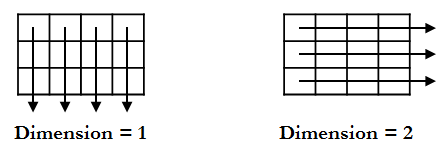

*Tomado de MATLAB Fundamentals (R2022a) de MathWorks.*

% Ingrese su código aquí :)

### Función `sortrows`

La función `sortrows` permite ordenar filas o columnas enteras entre sí, en función de una columna de referencia.

Notemos que este es un inconveniente con la anterior función `sort`, puesto que las columnas o filas son tratadas de forma independiente. Si no queremos que se pierda la relación entre fila y columna, es preferible utilizar esta función `sortrows`.

También se puede indicar a la función `sortrows`:

- **La columna de referencia:** depende de cuántas columnas tenga la matriz, pero si no se indica entonces se tomará como referencia la primera columna.

- **La dirección:** `'ascend'` (por defecto) o `'descend'`.

% Ingrese su código aquí :)

#### Observación

Para odernar por columnas en lugar de por filas, bastaría transponer la matriz.

% Ingrese su código aquí :)

## Matrices con otros tipos de datos

Hasta este momento hemos trabajado con matrices numéricas, puesto que los elementos de la matriz son números. En realidad son números tipo `double`. Pero también se pueden crear matrices con los otros tipos de datos que hemos estudiado hasta este momento.

**Lo único que se debe recordar es que una matriz debe contener únicamente elementos del mismo tipo de dato**.

#### Observación

A pesar que se especificó anteriormente una que un arreglo y una matriz no son lo mismo, generalmente algunos tipos de matrices en particular se los llama arreglo en lugar de matriz. Esto es únicamente debido a la forma en que se ha popularizado su nombre y, quizá, la mala traducción del inglés al español.

## Matriz cadena (arreglo cadena)

Una matriz cadena (o **arreglo cadena**) es una matriz que posee elementos tipo cadena (o **string**).

% Ingrese su código aquí :)

#### Observación

Crear una matriz utilizando cadenas y arreglos caracter dará como resultado un arreglo cadena. Lo mismo ocurre si se adjutan tipos de datos numéricos. Esta conversión se realiza para mantener la homogeneidad de la matriz.

% Ingrese su código aquí :)

### Funciones asociadas a arreglos cadena y arreglos caracter

Previamente se estudiaron diversas funciones para trabajar con cadenas o arreglos caracter. Pues bien, la mayoría de estas funciones también funcionan con matrices.

A esta forma de **trabajar con matrices y funciones se le llama vectorizar el código**, lo que mejora la eficiencia del código y proceso que se esté desarrollando.

A continuación se mostrarán algunas de las funciones para trabajar con cadenas y arreglos caracter utilizando matrices.

#### Función `str2double` y `double`

La función `str2double` permite crear un número tipo double a partir de una cadena. Es decir, convierte una cadena en un número.

% Ingrese su código aquí :)

#### Función `string`

La función `string` permite crear una cadena a partir de un número. Es decir, convierte un número en una cadena.

% Ingrese su código aquí :)

#### Observación

Si alguien se está preguntando por la función `num2str`, la cual quizá debimos haber usado, pues con esta función se debe tener cierto cuidado cuando se trabajan con matrices.

La función `num2str` crea un arreglo caracter, pero concatenará los elementos por filas. Quizá esto no sea lo deseado.

% Ingrese su código aquí :)

Una opción para corregir esto sería pasarle el vector fila como vector columna.

% Ingrese su código aquí :)

Sin embargo, lo que nos devuelve no es un vector columna. Lo que nos acaba de devolver es una matriz caracter (o arreglo caracter propiamente dicho).

Por esta razón se debe tener bastante precaución sobre lo que me devuelve una función: una cadena o un arreglo caracter. Ahora vemos que no son lo mismo y cada tipo de arreglo tiene diferentes propiedades.

#### Función `+`

Las funciones de suma para números permiten concatenar únicamente cadenas.

% Ingrese su código aquí :)

#### Observación

La función `plus` o `+` sólo sirve con cadenas. Para concatenar arreglos de caracteres se utiliza la función `append`.

#### Función `strlength`

La función `strlength` permite conocer el número de caracteres dentro de una cadena o un arreglo de caracteres.

% Ingrese su código aquí :)

Como se puede ver, las funciones de MATLAB se encuentran vectorizadas, por ende, podemos utilizarlas con escalares, vectores y matrices de manera directa e indistinta. Ahora queda a la imaginación, creatividad y necesidad del estudiante aplicar, conocer y familiarizarse con todas estas funciones.

Además, debido a que ya se introdujo el concepto de matriz, ahora el estudiante es capaz de leer y entender fácilmente la documentación de todas estas funciones, además de los ejemplos que ésta presenta. ¡Ánimo!

## Matriz caracter (arreglo caracter)

Una matriz caracter (o **arreglo caracter**) es una matriz que posee elementos tipo caracter (o **char**).

Las matrices caracter, o propiamente llamadas **arreglos caracter**, son un tipo especial de matrices. Antes de existir las cadenas (o **string**) como tal dentro de MATLAB, todo era caracter. Las cadenas son una forma más sencilla de trabajar con texto que los arreglos caracter. No obstante, bastantes funciones trabajan con arreglos caracter o devuelven un arreglo caracter.

**Una ventaja de los arreglos caracter es que son muchísimo más ligeros que los arreglos cadena**. Es decir, ocupan menos espacio de almacenamiento dentro de la computadora.

% Ingrese su código aquí :)

### Función `char` o `''`

Para crear un arreglo caracter se utiliza la función `char` o apóstrofes `''`.

% Ingrese su código aquí :)

Esto quizá no es el resultado deseado puesto que se están concatenando los nombres directamente. Una solución sería crear el arreglo con un vector columna, pero obtendremos un error.

¿Sabes por qué ocurre el error?

Ahora bien, la función `char` es la idónea para este trabajo. En la función `char` se deben ingresar los argumentos como caracter únicamente, y ésta ajustará el arreglo tal que sea consistente en sus dimensiones, rellenando con espacios en blanco para este fin.

% Ingrese su código aquí :)

#### Observación

En caso de tener un arreglo cadena el cual se quiera convertir a arreglo caracter, también es posible utilizar la función `char`, pero el arreglo cadena debe ser un vector cadena, caso contrario se creará un arreglo caracter multidimensional.

% Ingrese su código aquí :)

Los arreglos multidimensionales requieren su estudio propio, pero en resumidas cuentas son arreglos con objetos en tres o más dimensiones.

### Matriz lógica (o arreglo lógico)

Una matriz lógica (o **arreglo lógico**) es una matriz que posee elementos tipo lógico (o **logical**).

% Ingrese su código aquí :)

### Generar arreglos lógicos con operaciones relacionales

Recordemos brevemente las operaciones relacionales.

**Fig. 8.** Operaciones relacionales.

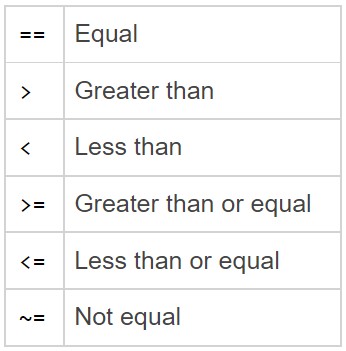

*Tomando de MATLAB Fundamentals (R2022a) de MathWorks.*

Ahora bien, estas operaciones también están vectorizadas. Es decir, también las podemos aplicar a matrices al igual que se hizo con escalares.

% Ingrese su código aquí :)

### Funciones asociadas a arreglos lógicos

Ahora que ya tenemos el concepto de arreglo lógico, es posible estudiar algunas funciones que nos serán de utilidad.

#### Función `all`

La función `all` es la conjunción dentro de una matriz. Es decir, si todos los elementos son `true` (o `1` lógico) entonces la salida es `1` lógico, caso contrario la salida es `0` lógico, es decir, `false`.

% Ingrese su código aquí :)

Pero si se aplica esta función sobre un arreglo lógico, entonces realizará la conjunción por la dimensión predominante.

% Ingrese su código aquí :)

No obstante, también se puede ingresar la dimensión secundaria para que se realice la conjunción por filas.

% Ingrese su código aquí :)

#### Función `any`

La función `any` es la disyunción dentro de una matriz. Es decir, si alguno de los elementos es `true` (o `1` lógico) entonces la salida es `1` lógico, caso contrario la salida es `0` lógico, es decir, `false`.

% Ingrese su código aquí :)

Pero si se aplica esta función sobre un arreglo lógico, entonces realizará la disyunción por la dimensión predominante.

% Ingrese su código aquí :)

No obstante, también se puede ingresar la dimensión secundaria para que se realice la disyunción por filas.

% Ingrese su código aquí :)

## Indexación de matrices

Indexar no es más que acceder a los elementos de una matriz a través de un índice. Aunque algunas formas no necesariamente utilizan índices, también se le conoce como indexación.

En MATLAB existen tres formas principales para acceder a los elementos de la matriz en función de su ubicación (índice) en la matriz. Estos enfoques son la indexación por posición, la indexación lineal (o sencilla) y la indexación lógica.

#### Observación

A continuación se realizarán las explicaciones de cada indexación con matrices numéricas por facilidad. No obstante, la indexación se utiliza con matrices de forma general, por ende, los conceptos que se estudiarán aplican para cualquier tipo de matriz.

### Indexación por posición

Analicemos la siguiente matriz.


$$A=\left\lbrack \begin{array}{ccc}
4_{1,1}  & 8_{1,2}  & 0_{1,3} \\
9_{2,1}  & 2_{2,2}  & 1_{2,3} \\
7_{3,1}  & 5_{3,2}  & 6_{3,3} 
\end{array}\right\rbrack$$


Observemos los índices de cada elemento. Pues bien, se pueden utilizar estos índices (también llamados subíndices) para indexar una matriz por posición. Al igual que la notación matemática, el primer índice indica el número de fila y el segundo índice indica el número de columna.

Es posible indexar:

- **Un único elemento:** Se indican los índices de posición del elemento.

- **Submatrices:** Se indican los índices de las filas y columnas que será extraídas.

- **Filas enteras:** Se indica el índice de la fila o filas, y para las columnas se escribe como índice el operador dos puntos `:`. 

- **Columnas enteras:** Se indica el índice de la columna o columnas, y para las filas se escribe como índice el operador dos puntos `:`.

El operador dos puntos `:` como índice vendría a significar **"todos los elementos"**. También se puede utilizar para indexar desde un índice hasta otro en lugar de escribir cada índice manualmente.

Un detalle a tener en cuenta es que los índices siempre son números enteros, matemáticamente hablando.

% Ingrese su código aquí :)

¿Qué se obtendrá como resultado del siguiente código?

#### Palabra reservada `end`

La palabra reservada `end` en indexación permite hacer referencia al último elemento de una matriz. En síntesis, es un número que es igual al último elemento de una matriz, independientemente del tamaño de la matriz.

% Ingrese su código aquí :)

Se tendría que seguir la misma lógica para obtener algún elemento empezando desde el final.

#### Convertir una matriz en un vector

En el caso de que se necesitase tener una matriz como un vector, se podría indexar fila a fila, o columna a columna, e ir concatenando estas filas, o columnas, para formar el vector. No obstante, el operador dos puntos `:` facilita optimiza este trabajo.

Para convertir una matriz en un vector se debe indexar la matriz únicamente con el operador dos puntos `:`.

% Ingrese su código aquí :)

Pero, ¿de qué forma transforma la matriz en vector? Con la siguiente indexación se detalla.

### Indexación lineal o sencilla

La indexación sencilla se realiza utilizando un único índice, o también denominado índice sencillo. Pero, ¿cómo indexar con un único índice? La siguiente imagen muestra el procedimiento que sigue MATLAB para hacer este tipo de indexación.

**Figura 9.** Proceso de indexación sencilla.

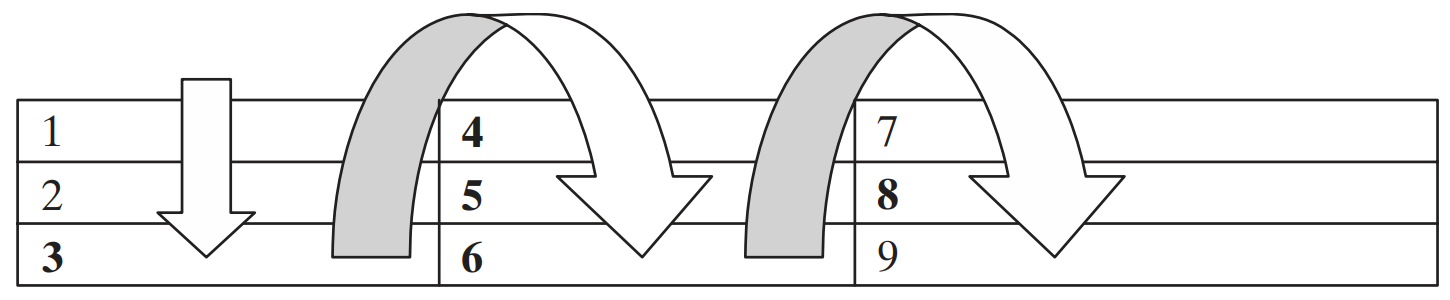

*Tomado de MATLAB para Ingenieros de Holly Moore*.

En la figura 1 podemos observar los índices sencillos de una matriz. Es así como funciona el transformar una matriz a un vector `A(:)`: apilar las columnas una debajo de otra de derecha a izquierda.

Analicemos la misma matriz anterior con sus índices sencillos:


$$A=\left\lbrack \begin{array}{ccc}
4_1  & 8_4  & 0_7 \\
9_2  & 2_5  & 1_8 \\
7_3  & 5_6  & 6_9 
\end{array}\right\rbrack$$


Con esta indexación únicamente podemos extraer:

- Elementos únicos.

- Vectores fila de elementos indicando los índices sencillos.

- Vectores fila de elementos utilizando el operador dos puntos.

Además que también es posible utilizar la palabra reservada `end` como con la anterior indexación.

% Ingrese su código aquí :)

#### Relación entre la indexación sencilla y la indexación por posición

#### Funciones `ind2sub` y `sub2ind`

En ocasiones quizá necesitemos convertir los índices sencillos a índices por posición (o subíndices), o viceversa. Con este fin podemos utilizar las funciones `ind2sub` (índice a subíndice) o `sub2ind` (subíndice a índice).

Notemos que la salida de la función `ind2sub` son dos variables, `row` y `col`. Por el momento entendamos que en la variable `row` se guardará el número de fila y en la variable `col` se guardará el número de columna.

Además, observemos también que estamos utilizando una función llamada `size`. Esta función permite conocer las dimensiones de un arreglo.

**Índice a subíndice**

**Figura 10.** Conversión de índices a subíndices.

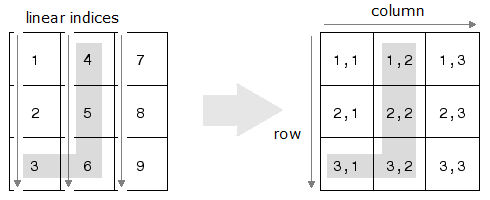

*Tomado de *[*MathWorks: *`ind2sub`](https://www.mathworks.com/help/matlab/ref/ind2sub.html).

**Subíndice a índice**

**Figura 11.** Conversión de subíndices a índices.

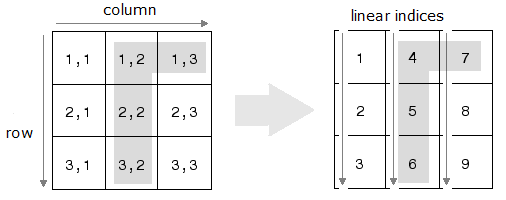

*Tomado de *[*MathWorks: *`sub2ind`](https://www.mathworks.com/help/matlab/ref/sub2ind.html).

Veámoslo con un ejemplo. Sea la matriz con la que hemos venido trabajando:


$$A=\left\lbrack \begin{array}{ccc}
4_{1,1}  & 8_{1,2}  & 0_{1,3} \\
9_{2,1}  & 2_{2,2}  & 1_{2,3} \\
7_{3,1}  & 5_{3,2}  & 6_{3,3} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
4_1  & 8_4  & 0_7 \\
9_2  & 2_5  & 1_8 \\
7_3  & 5_6  & 6_9 
\end{array}\right\rbrack$$


Notemos que se encuentran ambas indexaciones en cada matriz, donde los elementos son los mismos, únicamente varían los índices: en la matriz izquierda se encuentran los índices por posición (o subíndices) y en la matriz de la derecha se encuentran los índices sencillos.

% Ingrese su código aquí :)

### Indexación lógica

Para el análisis de la indexación lógica se tiene la siguiente figura.

**Figura 12.** Conversión de subíndices a índices.

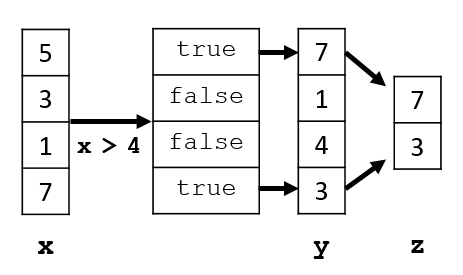

*Tomando de MATLAB Fundamentals (R2022a) de MathWorks.*

El uso de valores lógicos es otra forma útil de indexar matrices, especialmente cuando se trabaja con declaraciones condicionales.

Recordemos brevementos los valores lógicos.

% Ingrese su código aquí :)

Veámoslo con un ejemplo.

% Ingrese su código aquí :)

Notemos que únicamente se han indexado los elementos correspondientes al `1` lógico. Esta es la indexación lógica.

Además, recordemos que un arreglo lógico se puede obtener a partir de operaciones relacionales.

% Ingrese su código aquí :)

### Relación entre las 3 tipos de indexaciones

Existe una función extremadamente poderosa para determinar índices sencillos, índices por posición y los elementos de éstos índices. Además que se puede utilizar una condición lógica para facilitar búsquedas.

#### Función `find`

La función `find` permite determinar índices y valores de elementos distintos de cero. Aunque su potencial va más allá de esto.

Analicemos el uso de la función `find` únicamente con elementos diferentes de cero.

% Ingrese su código aquí :)

Ahora analicemos el potencial extra de la función `find`.

% Ingrese su código aquí :)

### Reemplazar elementos de una matriz

Utilizando cualquier tipo de indexación se puede reemplazar elementos de una matriz. Únicamente se indexan los elementos y se asignan los nuevos valores.

% Ingrese su código aquí :)

Esto funciona tanto para reemplazar un único elemento o varios elementos. Lo que se debe considerar es que la matriz que se indexa debe ser del mismo tamaño (tener las mismas dimensiones) que la matriz que reemplazará a la matriz indexada.

% Ingrese su código aquí :)

### Expandir una matriz

Una forma de expandir una matriz es concatenarla con otros elementos o matrices. No obstante, mediante indexación también es posible expandir una matriz.

Se debe indicar un índice fuera de rango de la matriz, es decir, que sea más grande que las dimensiones de la matriz y asignarle un valor o valores. Esto forzará a la matriz a expandirse rellenando los elementos en las posiciones que no se hayan asignado nada con ceros.

Lo que siempre se debe tener en cuenta es que la matriz resultante siempre debe ser consistente dimensionalmente hablando.

% Ingrese su código aquí :)

¿Cuál sería la matriz resultante del siguiente código?

### Eliminar elementos de una matriz

Para eliminar elementos de una matriz se utiliza la matriz vacía `[]`. Basta con utilizar cualquier indexación e indexar los elementos que se desean eliminar y asignarles la matriz vacía.

% Ingrese su código aquí :)

Esto funciona tanto para eliminar un único elemento o varios elementos. Lo que se debe considerar es que la matriz final debe ser consistente en sus dimensiones.

% Ingrese su código aquí :)

¿Cuál sería la matriz resultante del siguiente código?

## Matrices especiales

Dentro de MATLAB existen algunas funciones que permiten crear matrices con ciertas características, por lo que se las llaman matrices especiales.

### Función `zeros`

La función `zeros` permite crear una matriz $m\times n$ llena de ceros.

% Ingrese su código aquí :)

#### Observación

Si a la función `zeros` se le pasa únicamente un argumento, es decir, el valor de una sola dimensión, entonces se creará una matriz cuadrada llena de ceros del orden del argumento indicado.

% Ingrese su código aquí :)

### Función `ones`

La función `ones` permite crear una matriz $m\times n$ llena de unos.

% Ingrese su código aquí :)

#### Observación

Si a la función `ones` se le pasa únicamente un argumento, es decir, el valor de una sola dimensión, entonces se creará una matriz cuadrada llena de unos del orden del argumento indicado.

% Ingrese su código aquí :)

### Función `diag`

La función `diag` permite crear una matriz diagonal, la cual utilizará el vector ingresado como elementos d ela diagonal principal.

% Ingrese su código aquí :)

No obstante, si se le indica un segundo argumento a la función `diag`, el parámetro `k`, la función desplazará la diagonal como se muestra en la siguiente figura. 

**Figura 13.** Parámetro $k$ de la función `diag`.

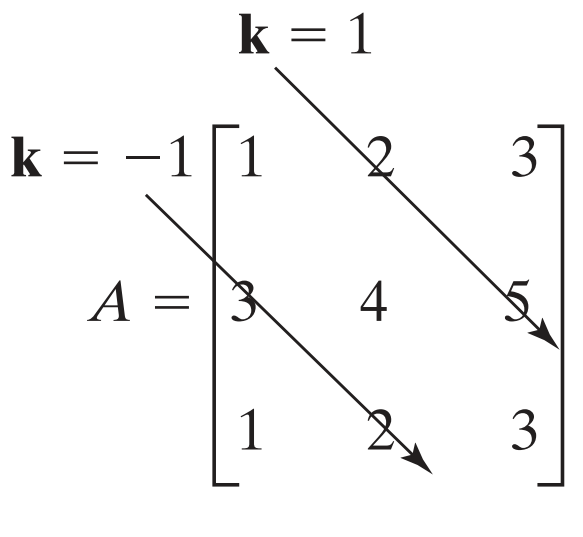

*Tomado de MATLAB para Ingenieros de Holly Moore.*

% Ingrese su código aquí :)

#### Observación

Si se pasa como argumento a la función `diag` una matriz en lugar de un vector, entonces esta función extraerá la diagonal de esta matriz. También es posible indicar mediante el parámetro `k` qué diagonal se quiere extraer.

% Ingrese su código aquí :)

## Material adicional

- [Creación, concatenación y expansión de matrices](https://www.mathworks.com/help/matlab/math/creating-and-concatenating-matrices.html)

- [Redimensionar y reorganizar matrices](https://www.mathworks.com/help/matlab/math/reshaping-and-rearranging-arrays.html)

- [Crear arreglos de cadenas](https://www.mathworks.com/help/matlab/matlab_prog/create-string-arrays.html)

- [Operaciones lógicas (o booleanas)](https://www.mathworks.com/help/matlab/logical-operations.html)

- [Indexación de arreglos](https://www.mathworks.com/help/matlab/math/array-indexing.html)

- [Encontrar elementos de una matriz que cumplan una condición](https://www.mathworks.com/help/matlab/matlab_prog/find-array-elements-that-meet-a-condition.html)

- [Función `find`](https://www.mathworks.com/help/matlab/ref/find.html)